# `GPS Position Plotting and Updating in a sequence for logged data`

`Enter The location of your logged data in .mat format below`

`For example: data = load('/home/hazem/MATLAB-Drive/MobileSensorData/sensorlog_RoadStraightY.mat')`

data = load('')

data = struct with fields:
       Acceleration: [8163×3 timetable]
      MagneticField: [7914×3 timetable]
        Orientation: [8163×3 timetable]
    AngularVelocity: [16326×3 timetable]
           Position: [7×6 timetable]


%Store needed data in vectors to be used in plotting.
latitudes = data.Position.latitude;
longitudes = data.Position.longitude;
markerSizes = data.Position.hacc.*10;
timestamps = seconds(diff(data.Position.Timestamp));

`And now we create the figure for GPS Coordinates plotting in a geobasemap.`

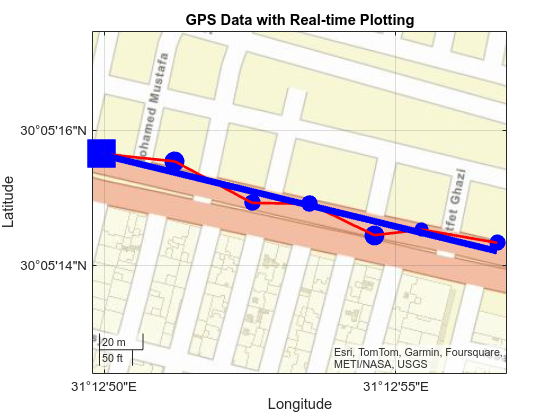

figure;
% Set up the geographic plot and base map
geobasemap('streets');  % Set the map to street view
hold on;

% Initialize the plot with the first point
geoscatter(latitudes(1), longitudes(1), markerSizes(1), "blue", "filled", "square");
title('GPS Data with Real-time Plotting');
bestFitLineHandle = [];
% Loop through each point, plot it, and update the best fit line
for i = 2:length(latitudes)
    % Plot the current point
    geoscatter(latitudes(i), longitudes(i), markerSizes(i), 'blue', 'filled');
    geoplot([latitudes(i-1), latitudes(i)], [longitudes(i-1), longitudes(i)], '-r', 'LineWidth', 2);

    p = polyfit(longitudes(1:i), latitudes(1:i), 1);
    
    %best fit line values over the longitude range
    lon_fit = linspace(min(longitudes(1:i)), max(longitudes(1:i)), 100);
    lat_fit = polyval(p, lon_fit);  %corresponding latitude values for the best fit line
    
    if ~isempty(bestFitLineHandle)
        delete(bestFitLineHandle);
    end
    
    bestFitLineHandle = geoplot(lat_fit, lon_fit, '-b', 'LineWidth', 5);

    pause(timestamps(i-1));  % Pause for the difference in timestamps
end

hold off;